Kaggle Titanic Competition

Load data

clear all
trainData_raw = readtable("data\train.csv");
testVectors_raw = readtable("data\test.csv");

testVectors_ans = readtable("data\test_ans.csv");


## Prepare data:

### Survived processing

trainData = trainData_raw;
trainData.Survived = categorical(trainData.Survived,[0, 1, 2],{'Died','Survived','N/A'});

%testVectors: add survived column as a categorical
testVectors = testVectors_raw;
[testVectors_size, ~] = size(testVectors);
testVectors.Survived = ones(testVectors_size,1)*2;
testVectors.Survived = categorical(testVectors.Survived,[0, 1, 2],{'Died','Survived','N/A'});
testVectors = [testVectors(:,1), testVectors(:,end), testVectors(:,2:end-1)];

Concatenate train and test data to create whole data set with categorical argument to distinguish them

temp = size(trainData,1);
trainData.TestVector = zeros(temp,1);
firstTestElement = temp + 1;
temp = size(testVectors,1);
testVectors.TestVector = ones(temp,1);

allData = [trainData; testVectors]

allData = 1309×13 table
    PassengerId    Survived    Pclass                             Name                                 Sex        Age    SibSp    Parch      Ticket       Fare       Cabin       Embarked    TestVector
    ___________    ________    ______    _______________________________________________________    __________    ___    _____    _____    __________    ______    __________    ________    __________

         1         Died          3       {'Braund, Mr. Owen Harris'                            }    {'male'  }     22      1        0


clear temp

### Pclass processing

allData.Pclass = categorical(allData.Pclass,[1, 2, 3],{'FirstClass','SecondClass','ThirdClass'});

compare_columns(allData,'Pclass','Survived', ...
    "Passengers' Classes", "Number of passengers", ...
    "Difference between number of passengers vs. their class")

There is no missing values and rougly there is correlation between class and change of survival.

### Name processing

Name variable is containing several data: name, second name and title. While name seems to be random, second name is gatering people in one family. Also title is sort of information. Lets split this string to three separate values.

names = split_names(allData);
%we are going to skip Other_name as not relevant
allData = [allData(:,1:3) names(:,1:2) allData(:,5:end)];
clear names

allData.Title = categorical(allData.Title);

compare_columns(allData,'Title','Survived', ...
    "Passengers' Titles", "Number of passengers", ...
    "Difference between number of passengers vs. their title")

allData.Title = mergecats(allData.Title,{'Military','Capt','Col','Major'});
allData.Title = mergecats(allData.Title,{'Noble male','Don','Sir','Jonkheer'});
allData.Title = mergecats(allData.Title,{'Noble female','Dona','Mme','the Countess','Lady'});
allData.Title = mergecats(allData.Title,{'Miss','Mlle'});
allData.Title = mergecats(allData.Title,{'Mrs','Ms'});

compare_columns(allData,'Title','Survived', ...
    "Passengers' Titles", "Number of passengers", ...
    "Difference between number of passengers vs. their title")

Miss and Mrs seems to have same rate of survival, so title for woman may not be importand.

allMrsSurvived = max(countcats(allData{allData.Title == 'Mrs' & allData.Survived == 'Survived','Title'}));
allMissSurvived = max(countcats(allData{allData.Title == 'Miss' & allData.Survived == 'Survived','Title'}));

allMrsDied = max(countcats(allData{allData.Title == 'Mrs' & allData.Survived == 'Died','Title'}));
allMissDied = max(countcats(allData{allData.Title == 'Miss' & allData.Survived == 'Died','Title'}));

survivalRatioMrs = allMrsSurvived / (allMrsSurvived + allMrsDied)

survivalRatioMrs = 0.7937

survivalRatioMiss = allMissSurvived / (allMissSurvived + allMissDied)

survivalRatioMiss = 0.7011


allData.Title = mergecats(allData.Title,{'Mrs','Miss','Noble female'});

compare_columns(allData,'Title','Survived', ...
    "Passengers' Titles", "Number of passengers", ...
    "Difference between number of passengers vs. their title")

clear allMrsSurvived allMissSurvived allMrsDied allMissDied

Noble male like military and rev keeps low level but very simillar survival ratio

allNobleMaleSurvived = max(countcats(allData{allData.Title == 'Noble male' & allData.Survived == 'Survived','Title'}));
allMrSurvived = max(countcats(allData{allData.Title == 'Mr' & allData.Survived == 'Survived','Title'}));

allNobleMaleDied = max(countcats(allData{allData.Title == 'Noble male' & allData.Survived == 'Died','Title'}));
allMrDied = max(countcats(allData{allData.Title == 'Mr' & allData.Survived == 'Died','Title'}));

survivalRatioNobleMale = allNobleMaleSurvived / (allNobleMaleSurvived + allMrSurvived)

survivalRatioNobleMale = 0.0122

survivalRatioMr = allNobleMaleDied / (allNobleMaleDied + allMrDied)

survivalRatioMr = 0.0046


allData.Title = mergecats(allData.Title,{'Noble male','Military','Rev'});

compare_columns(allData,'Title','Survived', ...
    "Passengers' Titles", "Number of passengers", ...
    "Difference between number of passengers vs. their title")

clear allNobleMaleSurvived allMrSurvived allNobleMaleDied allMrDied

### Sex processing

allData.Sex = categorical(allData.Sex);

compare_columns(allData,'Sex','Survived', ...
    "Passengers' sex", "Number of passengers", ...
    "Difference between number of passengers vs. their sex")

compare_columns(allData,'Sex','Pclass', ...
    "Passengers' sex", "Passengers' class", ...
    "Difference between passengers's class vs. their sex")


Three conclusion here:

- in third class there were significantly more male than females 

- males are more likely to not survive

- third class is more likely to not survive

It is not so obvious here if they died because of beeing male or because of beeing in third class.

Right now Sex is reflected in Title feature. However Title contains more information beside sex, so sex can be reduced.

### Age processing

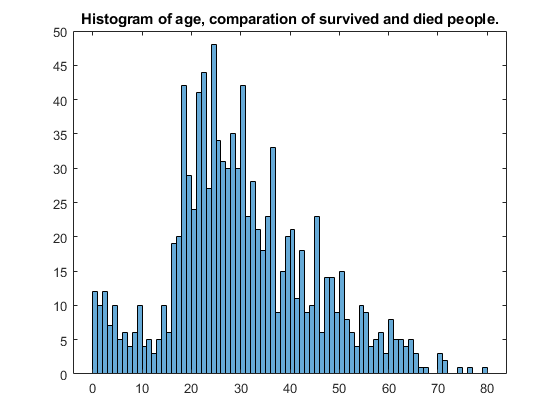

figure
xlabel("Age")
ylabel("Number of died")
histogram(allData{:,"Age"},80)
title('Histogram of age, comparation of survived and died people.')

Observation: 

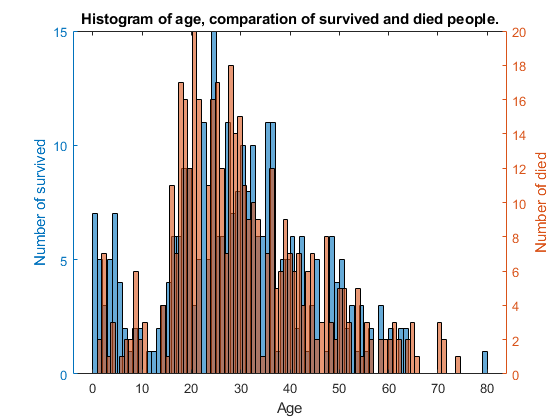


figure
yyaxis left
histogram(allData{allData.Survived == 'Survived',"Age"},80)
xlabel("Age")
ylabel("Number of survived")
yyaxis right
histogram(allData{allData.Survived == 'Died',"Age"},80)
ylabel("Number of died")
title('Histogram of age, comparation of survived and died people.')

There are some missing data in 'Age' column.

It can be filled with mean values:

- of all passengers

- of passengers from simillar class

- of passengers from simillar gender

- mixture of class and gender

males_firstClass_over16 = allData.Sex == 'male' & allData.Pclass == 'FirstClass' & allData.Age > 16;
males_secondClass_over16 = allData.Sex == 'male' & allData.Pclass == 'SecondClass' & allData.Age > 16;
males_thirdClass_over16 = allData.Sex == 'male' & allData.Pclass == 'ThirdClass' & allData.Age > 16;

[male.firstclass.mean, male.firstclass.median, male.firstclass.count] = stats_subtable(allData,males_firstClass_over16,'Age','omitnan');
[male.secondclass.mean, male.secondclass.median, male.secondclass.count] = stats_subtable(allData,males_secondClass_over16,'Age','omitnan');
[male.thirdclass.mean, male.thirdclass.median, male.thirdclass.count] = stats_subtable(allData,males_thirdClass_over16,'Age','omitnan');

males_missingAge = allData.Sex == 'male' & ismissing(allData.Age);
males_missignAge_noRelatives = males_missingAge & allData.SibSp == 0 & allData.Parch == 0;

males_missingAge_1st_noRelatives = allData.Pclass == 'FirstClass' & males_missignAge_noRelatives;
males_missingAge_2nd_noRelatives = allData.Pclass == 'SecondClass' & males_missignAge_noRelatives;
males_missingAge_3rd_noRelatives = allData.Pclass == 'ThirdClass' & males_missignAge_noRelatives;

allData{males_missingAge_1st_noRelatives,"Age"} = male.firstclass.median;
allData{males_missingAge_2nd_noRelatives,"Age"} = male.secondclass.median;
allData{males_missingAge_3rd_noRelatives,"Age"} = male.thirdclass.median;

%females time
females_firstClass_over16 = allData.Sex == 'female' & allData.Pclass == 'FirstClass' & allData.Age > 16;
females_secondClass_over16 = allData.Sex == 'female' & allData.Pclass == 'SecondClass' & allData.Age > 16;
females_thirdClass_over16 = allData.Sex == 'female' & allData.Pclass == 'ThirdClass' & allData.Age > 16;

[female.firstclass.mean, female.firstclass.median, female.firstclass.count] = stats_subtable(allData,females_firstClass_over16,'Age','omitnan');
[female.secondclass.mean, female.secondclass.median, female.secondclass.count] = stats_subtable(allData,females_secondClass_over16,'Age','omitnan');
[female.thirdclass.mean, female.thirdclass.median, female.thirdclass.count] = stats_subtable(allData,females_thirdClass_over16,'Age','omitnan');

females_missingAge = allData.Sex == 'female' & ismissing(allData.Age);
females_missignAge_noRelatives = females_missingAge & allData.SibSp == 0 & allData.Parch == 0;

females_missingAge_1st_noRelatives = allData.Pclass == 'FirstClass' & females_missignAge_noRelatives;
females_missingAge_2nd_noRelatives = allData.Pclass == 'SecondClass' & females_missignAge_noRelatives;
females_missingAge_3rd_noRelatives = allData.Pclass == 'ThirdClass' & females_missignAge_noRelatives;

allData{females_missingAge_1st_noRelatives,"Age"} = female.firstclass.median;
allData{females_missingAge_2nd_noRelatives,"Age"} = female.secondclass.median;
allData{females_missingAge_3rd_noRelatives,"Age"} = female.thirdclass.median;

clear males_firstClass_over16 males_secondClass_over16 males_thirdClass_over16
clear males_missingAge males_missignAge_noRelatives
clear males_missingAge_1st_noRelatives males_missingAge_2nd_noRelatives males_missingAge_3rd_noRelatives
clear females_firstClass_over16 females_secondClass_over16 females_thirdClass_over16
clear females_missingAge females_missignAge_noRelatives
clear females_missingAge_1st_noRelatives females_missingAge_2nd_noRelatives females_missingAge_3rd_noRelatives

There is some error included. Some passengers were below 16 years od without relatives onboard. Assigning adult median value to all empty 'Age' may move some children to adult group. But number is not significat in terms of whole number of gender representatives. 

There is also assumption, that siblings are really siblings. But spouse with parents is also possible. 

There is still some missing values, but passengers are traveling with relatives. 

males_firstClass_under18 = allData.Sex == 'male' & allData.Pclass == 'FirstClass' & allData.Age < 18;
males_secondClass_under18 = allData.Sex == 'male' & allData.Pclass == 'SecondClass' & allData.Age < 18;
males_thirdClass_under18 = allData.Sex == 'male' & allData.Pclass == 'ThirdClass' & allData.Age < 18;

[youngmale.firstclass.mean, youngmale.firstclass.median, youngmale.firstclass.count] = stats_subtable(allData,males_firstClass_under18,'Age','omitnan');
[youngmale.secondclass.mean, youngmale.secondclass.median, youngmale.secondclass.count] = stats_subtable(allData,males_secondClass_under18,'Age','omitnan');
[youngmale.thirdclass.mean, youngmale.thirdclass.median, youngmale.thirdclass.count] = stats_subtable(allData,males_thirdClass_under18,'Age','omitnan');

clear males_firstClass_under18 males_secondClass_under18 males_thirdClass_under18

Assumption here, that all Masters and passengers with Parch > 0 and SibSp are young (parent with other siblings).

males_missingAge = (allData.Title == 'Master'| (allData.Parch > 0 & allData.SibSp > 0)) & ismissing(allData.Age);

males_missingAge_1st = allData.Pclass == 'FirstClass' & males_missingAge;
males_missingAge_2nd = allData.Pclass == 'SecondClass' & males_missingAge;
males_missingAge_3rd = allData.Pclass == 'ThirdClass' & males_missingAge;

allData{males_missingAge_1st,"Age"} = youngmale.firstclass.median;
allData{males_missingAge_2nd,"Age"} = youngmale.secondclass.median;
allData{males_missingAge_3rd,"Age"} = youngmale.thirdclass.median;

clear males_missingAge males_missingAge_1st males_missingAge_2nd males_missingAge_3rd

No females with the same scenario. In fact Miss doesn't guarantee that female is under 18.

Now we can assume, that passengers with sibblings or sposue are more or less in the same age.

all_missingAge = ismissing(allData.Age) & allData.SibSp > 0;
sameNames = allData(all_missingAge,:);
[sameNames_size, ~] = size(sameNames);
for idx = 1:sameNames_size
    idx_name_value = sameNames{idx,'Name'};
    idx_record_value = sameNames{idx,'PassengerId'};
    %%special characters from Ticket shall be removed
    %%tbd
    idx_ticket_value = sameNames{idx,'Ticket'}; %strcmp(allData.Name, idx_name_value) &
    other = allData( allData.Ticket == idx_ticket_value & ~ismissing(allData.Age),:);
    x = max(other.Age);
    if ~isempty(x)
        allData{allData.PassengerId == idx_record_value,"Age"} = x+2;
    end
end

Other data fill with median value.

allData{ismissing(allData.Age) & allData.Sex == "male" & allData.Pclass == "FirstClass" ,'Age'} = male.firstclass.median;
allData{ismissing(allData.Age) & allData.Sex == "female" & allData.Pclass == "FirstClass" ,'Age'} = female.firstclass.median;
allData{ismissing(allData.Age) & allData.Sex == "male" & allData.Pclass == "SecondClass" ,'Age'} = male.secondclass.median;
allData{ismissing(allData.Age) & allData.Sex == "female" & allData.Pclass == "SecondClass" ,'Age'} = female.secondclass.median;
allData{ismissing(allData.Age) & allData.Sex == "male" & allData.Pclass == "ThirdClass" ,'Age'} = male.thirdclass.median;
allData{ismissing(allData.Age) & allData.Sex == "female" & allData.Pclass == "ThirdClass" ,'Age'} = female.thirdclass.median;


Discretize age

age_names = {'Child','Teenage','YoungAdult','Adult','Mature','Old'};
allData.Age = discretize(allData.Age,[0 12 18 24 30 50 100],'categorical',age_names);

### Fare processing

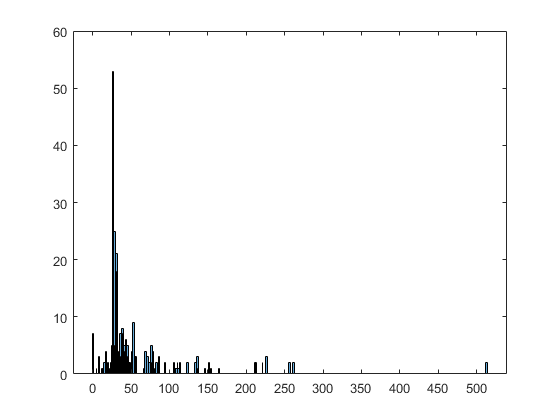

allData.Embarked = categorical(allData.Embarked);

allData.PassNo = allData.SibSp+allData.Parch+1;
allData.Fare_new = allData.Fare./allData.PassNo;

fare_1Class = allData(allData.Pclass == "FirstClass",["Fare", "SibSp", "Parch", "Embarked", "PassNo", "Fare_new", "Cabin"]);
fare_2Class = allData(allData.Pclass == "SecondClass",["Fare", "SibSp", "Parch", "Embarked", "PassNo", "Fare_new", "Cabin"]);
fare_3Class = allData(allData.Pclass == "ThirdClass",["Fare", "SibSp", "Parch", "Embarked", "PassNo", "Fare_new", "Cabin"]);

fare1Class_C = fare_1Class(fare_1Class.Embarked == 'C',:);
fare2Class_C = fare_2Class(fare_2Class.Embarked == 'C',:);
fare3Class_C = fare_3Class(fare_3Class.Embarked == 'C',:);

fare1Class_S = fare_1Class(fare_1Class.Embarked == 'S',:);
fare2Class_S = fare_2Class(fare_2Class.Embarked == 'S',:);
fare3Class_S = fare_3Class(fare_3Class.Embarked == 'S',:);

fare1Class_Q = fare_1Class(fare_1Class.Embarked == 'Q',:);
fare2Class_Q = fare_2Class(fare_2Class.Embarked == 'Q',:);
fare3Class_Q = fare_3Class(fare_3Class.Embarked == 'Q',:);

figure
histogram(fare1Class_C.Fare_new,200)
hold on
histogram(fare1Class_S.Fare_new,200)
histogram(fare1Class_Q.Fare_new,200)
hold off

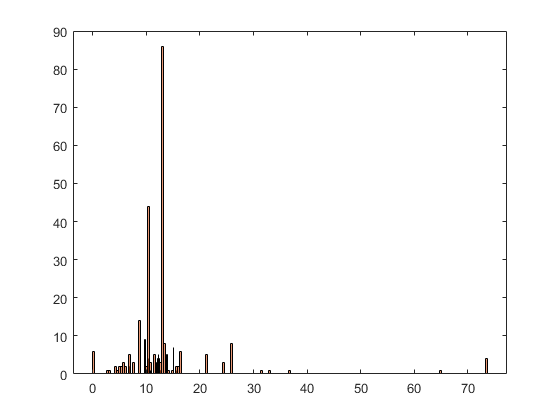

figure
histogram(fare2Class_C.Fare_new,200)
hold on
histogram(fare2Class_S.Fare_new,200)
histogram(fare2Class_Q.Fare_new,200)
hold off

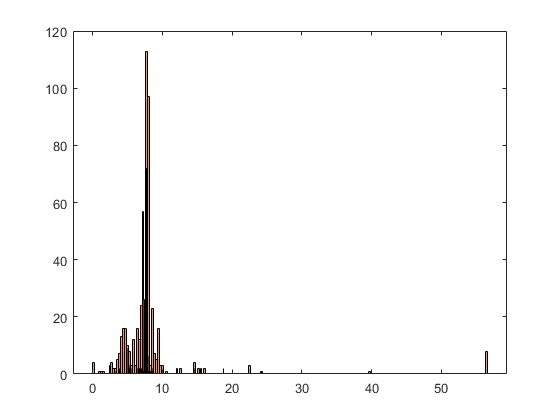

figure
histogram(fare3Class_C.Fare_new,200)
hold on
histogram(fare3Class_S.Fare_new,200)
histogram(fare3Class_Q.Fare_new,200)
hold off


clear fare1Class_C fare2Class_C fare3Class_C
clear fare1Class_S fare2Class_S fare3Class_S
clear fare1Class_Q fare2Class_Q fare3Class_Q

There is no visible impact of embarking place on ticket price. 

[priceC.c1st.mean, priceC.c1st.median, priceC.c1st.count] = stats_subtable(fare_1Class,fare_1Class.Embarked == 'C','Fare_new','omitnan');
[priceC.c2st.mean, priceC.c2st.median, priceC.c2st.count] = stats_subtable(fare_2Class,fare_2Class.Embarked == 'C','Fare_new','omitnan');
[priceC.c3st.mean, priceC.c3st.median, priceC.c3st.count] = stats_subtable(fare_3Class,fare_3Class.Embarked == 'C','Fare_new','omitnan');

[priceS.c1st.mean, priceS.c1st.median, priceS.c1st.count] = stats_subtable(fare_1Class,fare_1Class.Embarked == 'S','Fare_new','omitnan');
[priceS.c2st.mean, priceS.c2st.median, priceS.c2st.count] = stats_subtable(fare_2Class,fare_2Class.Embarked == 'S','Fare_new','omitnan');
[priceS.c3st.mean, priceS.c3st.median, priceS.c3st.count] = stats_subtable(fare_3Class,fare_3Class.Embarked == 'S','Fare_new','omitnan');

[priceQ.c1st.mean, priceQ.c1st.median, priceQ.c1st.count] = stats_subtable(fare_1Class,fare_1Class.Embarked == 'Q','Fare_new','omitnan');
[priceQ.c2st.mean, priceQ.c2st.median, priceQ.c2st.count] = stats_subtable(fare_2Class,fare_2Class.Embarked == 'Q','Fare_new','omitnan');
[priceQ.c3st.mean, priceQ.c3st.median, priceQ.c3st.count] = stats_subtable(fare_3Class,fare_3Class.Embarked == 'Q','Fare_new','omitnan');


There are some differences when it comes to 1st class. I would prefer to reduce this feature it is doubling class selection. 

Prices can be used to fill in cabin feature.

allData.Fare = allData.Fare_new;
allData.Fare_new = [];
allData.PassNo = [];


### SibSp and Psrch processing

[dataSize, ~] = size(allData);
%categories(allData.Sex)

allData.Female_Relatives = zeros(dataSize,1);
%allData.Male_Relative = zeros(dataSize,1);

for idx = 1:dataSize
    ticketNo = allData{idx,'Ticket'};
    sex = allData{idx,'Sex'};
    noOfRelatives = allData{idx,'SibSp'}+allData{idx,'Parch'};
    female_rel = 0;
    male_rel = 0;
    if noOfRelatives > 0
      if isnumeric(ticketNo)
          allRelatives = countcats(allData{allData.Ticket == ticketNo,'Sex'});
      else
          name = allData{idx,'Name'};
          allRelatives = countcats(allData{strcmp(allData.Name, name),'Sex'});
      end
      if sum(allRelatives)-1 >= noOfRelatives
            female_rel = allRelatives(1);
            male_rel = allRelatives(2);        
      end
    end
    if female_rel > 0
        %allData{idx,'Female_Relatives'} = female_rel;
    end
    if male_rel > 0
        %allData{idx,'Male_Relatives'} = male_rel;
    end
    allData{idx,'Female_Relatives'} = noOfRelatives;
end

relatives_names = {'Alone','Spouse','SmallFamily','BigFamily'};
allData.Female_Relatives = discretize(allData.Female_Relatives,[0 1 2 4 10],'categorical',relatives_names);

### Cabin processing


%func(allData.Cabin(1))
%splitted = rowfun(func,allData(:,'Cabin'),'OutputVariableNames','z')
%splitted =  regexpi(allData.Cabin,'([A-Z])[0-9]+','match','once')
%splitted = allData.Cabin
splitted2 = arrayfun(@(y) get_first_letter(char(y)),allData.Cabin);
allData.Deck = splitted2;
allData.Deck = categorical(allData.Deck);

allData(allData{:,"Pclass"} == "FirstClass",["Deck","Fare"]);
allData(allData{:,"Pclass"} == "SecondClass",["Deck","Fare"]);
allData(allData{:,"Pclass"} == "ThirdClass",["Deck","Fare"]);


Different decks gives different survival ratio

compare_columns(allData,'Deck','Survived', ...
    "Passengers' Deck", "Number of passengers", ...
    "Difference between number of passengers vs. their deck")

T_1st_class = 7;
A_1st_class = 48;
B_1st_class = 183;
C_1st_class = 315;

D_1st_class = 119;
D_2nd_class = 119;
D_3rd_class = 2;

E_3st_class = 184;
F_3rd_class = 10;
G_3rd_class = 6;

%[dataSize, ~] = size(allData);
%for idx = 1:dataSize
    %splitted =  regexpi(allData.Cabin{idx},'([A-Z])[0-9]+','tokens');
    %[~, cabs_no] = size(splitted);
    %if cabs_no > 0
    %    idx
    %    old_x = {''};
    %    for val = 1:cabs_no
    %        new_x = splitted{val};
    %        if ~strcmp(old_x, {''}) & ~strcmp(new_x, old_x)
    %            new_x
    %        end
    %        old_x = new_x;
    %    end
    %end

%end



Remove Sex feature - Title holds all data

columns_names = allData.Properties.VariableNames;
columns_names(ismember(columns_names,'Survived')) = [];
columns_names(ismember(columns_names,'TestVector')) = [];
columns_names(ismember(columns_names,'PassengerId')) = [];
columns_names(ismember(columns_names,'Ticket')) = [];
columns_names(ismember(columns_names,'Name')) = [];
columns_names(ismember(columns_names,'Cabin')) = [];

columns_names(ismember(columns_names,'Fare')) = [];
columns_names(ismember(columns_names,'SibSp')) = [];
columns_names(ismember(columns_names,'Deck')) = [];
columns_names(ismember(columns_names,'Parch')) = [];
columns_names(ismember(columns_names,'Sex')) = [];
columns_names(ismember(columns_names,'Age')) = [];
columns_names(ismember(columns_names,'Embarked')) = [];
columns_names(ismember(columns_names,'Female_Relatives')) = [];


Search for missing values

trainDataMissingMatrix = ismissing(allData);
trainData_misingVariablesCount = sum(trainDataMissingMatrix)

trainData_misingVariablesCount =            0           0           0           0           0           0           0           0           0         352           1        1014           2           0           0           0



allData.Survived = renamecats(allData.Survived,{'Died','Survived','N/A'},{'0', '1', '2'});

trainDataP = allData(1:firstTestElement-1,:)

trainDataP = 891×16 table
    PassengerId    Survived      Pclass            Name          Title      Sex         Age        SibSp    Parch      Ticket       Fare       Cabin       Embarked    TestVector    Female_Relatives    Deck
    ___________    ________    ___________    _______________    ______    ______    __________    _____    _____    __________    ______    __________    ________    __________    ________________    ____

         1       

testVectorsP = allData(firstTestElement:end,:)

testVectorsP = 418×16 table
    PassengerId    Survived      Pclass           Name         Title     Sex         Age        SibSp    Parch      Ticket       Fare       Cabin       Embarked    TestVector    Female_Relatives    Deck
    ___________    ________    ___________    _____________    _____    ______    __________    _____    _____    __________    ______    __________    ________    __________    ________________    ____

        892          

Create table with dummu vars

%trainDataP_dummyVar = convert_to_dummyvar(trainDataP,'Embarked');
%trainDataP_dummyVar = convert_to_dummyvar(trainDataP_dummyVar,'Sex');
%trainDataP_dummyVar = convert_to_dummyvar(trainDataP_dummyVar,'Title');
%trainDataP_dummyVar = convert_to_dummyvar(trainDataP_dummyVar,'Pclass');

%trainDataP_dummyVar.Name = []

%trainDataP_normalised = normalize(trainDataP_dummyVar(:,2:end));
%XTrain_norm = table2array(trainDataP_normalised);

%[pc, score, ~, ~, pexp] = pca(XTrain_norm);
%pareto(pexp)
%scatter(score(:,1),score(:,2))

%trainDataP.Name = [];
%testVectorsP.Name = [];
trainDataP.TestVector = [];
testVectorsP.TestVector = [];


%change to separate values
if(false)
    
end


template = templateSVM('KernelFunction','');

 
%model{1} = fitcecoc(trainDataP,"Survived",'Learners',template);
%model{2} = fitcsvm(trainDataP,"Survived",'KernelFunction','gaussian');
%model{3} = fitcknn(trainDataP,"Survived","NumNeighbors",10);
%model{4} = fitctree(trainDataP,"Survived");
%model{5} = fitcnb(trainDataP,"Survived","DistributionNames",["mvmn","mvmn","mvmn","mvmn"]);

result_table = table();
model_index = 1;

surv_pred_cost = 1;
died_pred_cost = 1;

subsColumns = nchoosek(columns_names,2);

for selected_columns_idex = 1:size(subsColumns,1)
    
    selected_columns = subsColumns(selected_columns_idex,:)%{'Pclass','Title'};
    
    possible_prior = ["empirical"];%,"uniform"]
    
    for priori_idex = 1:length(possible_prior)
    
        for inclties_idex = true%[true,false]
        
            for standarize_idex = true %false 
                %true cannot be used when all predictors are categorical
                if standarize_idex == true
                    categorical_predictors_val = [];
                    %change to numbers
                    for cat_index = selected_columns
                        [~, ~, temp ] = unique(trainDataP(:,cat_index));
                        trainDataP(:,cat_index) = [];
                        trainDataP(:,cat_index) = table(temp);
                        [~, ~, temp] = unique(testVectorsP(:,cat_index));
                        testVectorsP(:,cat_index) = [];
                        testVectorsP(:,cat_index) = table(temp);
                    end
                    %[~, ~, trainDataP.Pclass] = unique(trainDataP.Pclass);
                    %[~, ~, trainDataP.Title] = unique(trainDataP.Title);
                    %[~, ~, trainDataP.Age] = unique(trainDataP.Age);
                    %[~, ~, trainDataP.Female_Relatives] = unique(trainDataP.Female_Relatives)
                    
                    %[~, ~, testVectorsP.Pclass] = unique(testVectorsP.Pclass);
                    %[~, ~, testVectorsP.Title] = unique(testVectorsP.Title);
                    %[~, ~, testVectorsP.Age] = unique(testVectorsP.Age);
                    %[~, ~, testVectorsP.Female_Relatives] = unique(testVectorsP.Female_Relatives)
                    
                    %trainDataP_normalised = normalize(trainDataP_dummyVar(:,2:end));
                    %XTrain_norm = table2array(trainDataP_normalised);
                    %[pc, score, ~, ~, pexp] = pca(XTrain_norm);
                    %pareto(pexp)
                    %scatter(score(:,1),score(:,2))
                else
                    categorical_predictors_val = 'all';
                end
                for surv_pred_cost = 1%0.6%0.4:0.2:1
                    
                    for died_pred_cost = 1%0.2%0.2:0.2:0.4
                
                        possible_distanceweight = ["equal"];
                        %"inverse","squaredinverse",
                
                        for distanceweight_idex = 1:length(possible_distanceweight)
                        
                            possible_breakTies = ["smallest","nearest","random"];
                            % smallest - wybiera klasę pierwszego z brzegu elementu
                            % nearest - wybiera klasę elementy najbliższego
                            % random - losowa klasa
                            
                            for breakties_idex = 1:length(possible_breakTies)
                                fprintf("Loop: %s\n",possible_breakTies(breakties_idex));
    
                                possible_methods = ["exhaustive","kdtree"];
                                
                                
                                
                                for met_idex = 1:length(possible_methods)
                                                                    
                                    if met_idex == 2
                                        possible_distances = ["euclidean","cityblock","minkowski"];
                                        %,"chebychev"
                                        bucked_size = 20:50;
                                    else
                                        possible_distances = ["mahalanobis","seuclidean"];
                                        %"cosine","hamming","jaccard","correlation","spearman" removed - cannot be used in this
                                        bucked_size = [50];
                                        
                                    end
                                    
                                    for bucked_size_idex = 1:length(bucked_size)
                                        for neighbors_num = 2:11
                                            for dist_idex = 1:length(possible_distances)
                                                result_table_row = table();
                                                result_table_row.ModelNo = model_index;
                                                result_table_row.Distance = possible_distances(dist_idex);
                                                result_table_row.Method = possible_methods(met_idex);
                                                result_table_row.NeighborsNum = neighbors_num;
                                                result_table_row.BreakTies = possible_breakTies(breakties_idex);
                                                result_table_row.DistanceWeight = possible_distanceweight(distanceweight_idex);
                                                result_table_row.BucketSize = bucked_size(bucked_size_idex);
                                                result_table_row.Cost = [died_pred_cost, surv_pred_cost];
                                                result_table_row.IncludeTies = inclties_idex;
                                                result_table_row.Standardize = standarize_idex;
                                                result_table_row.Prior = possible_prior(priori_idex);
                                                result_table_row.Selected_Columns = selected_columns;
                                                mdl = fitcknn(trainDataP,"Survived","NumNeighbors",neighbors_num,'NSMethod',possible_methods{met_idex},...
                                                    'Distance',possible_distances{dist_idex},'CategoricalPredictors',categorical_predictors_val,...
                                                    'BreakTies',possible_breakTies{breakties_idex},'ClassNames',{'0','1'},'Cost',[0, surv_pred_cost; died_pred_cost, 0],...
                                                    'IncludeTies',inclties_idex,'Standardize',standarize_idex,...
                                                    'Prior',possible_prior{priori_idex},'BucketSize',bucked_size_idex,...
                                                    'DistanceWeight',possible_distanceweight(distanceweight_idex),...
                                                     'PredictorNames',selected_columns);
                                                result_table_row.TrainError = resubLoss(mdl);
                                                ex_da = predict(mdl,testVectorsP);
                                                exit_data(:,1) = double(string(ex_da));
                                                errors = sum(exit_data(:,1) ~= testVectors_ans{:,'Survived'});
                                                error_rate = errors/418;
                                                result_table_row.Score = 1 - error_rate;
                                                model_index = model_index + 1;
                                                result_table = [result_table; result_table_row];
                                            end
                                        end
                                    end
                                end
                                result_table = sortrows(result_table,'Score',"descend");
                                result_table = result_table(1:20,:);
                            end
                        end
                    end
                end
            end
        end
    end
end

selected_columns = 1×2 cell array
    {'Pclass'}    {'Title'}


Loop: smallest
Loop: nearest
Loop: random



result_table = result_table(1:20,:)

result_table = 20×14 table
    ModelNo     Distance       Method     NeighborsNum    BreakTies    DistanceWeight    BucketSize     Cost     IncludeTies    Standardize       Prior          Selected_Columns        TrainError     Score 
    _______    ___________    ________    ____________    _________    ______________    __________    ______    ___________    ___________    ___________    _______________________    __________    _______

     2651      "cityblock"    "kdtree"         5          "random"        "equal" 


save(sprintf('./result_table_%s',datetime('now','format','yyyy_MM_dd_HH_mm_ss')),'result_table')

%choose best result
param_index = 1;
repetition_count = 1;

error_rate = zeros(repetition_count,1);

if result_table.Standardize(param_index) == true
    categorical_predictors_val = [];
else
    categorical_predictors_val = 'all';
end

for repetition_index = 1:repetition_count
    mdl = fitcknn(trainDataP,"Survived","NumNeighbors",result_table.NeighborsNum(param_index),'NSMethod',result_table.Method(param_index),...
                                                 'Distance',result_table.Distance(param_index),'CategoricalPredictors',categorical_predictors_val,...
                                                 'BreakTies',result_table.BreakTies(param_index),'ClassNames',{'0','1'},'Cost',[0, result_table.Cost(param_index,2); result_table.Cost(param_index,1), 0],...
                                                 'IncludeTies',result_table.IncludeTies(param_index),'Standardize',result_table.Standardize(param_index),...
                                                 'Prior',result_table.Prior(param_index),'BucketSize',result_table.BucketSize(param_index),...
                                                 'DistanceWeight', result_table.DistanceWeight(param_index),...
                                                 'PredictorNames',selected_columns);
    ex_da2 = predict(mdl,testVectorsP);
    exit_data2(:,1) = double(string(ex_da2));
    
    errors = sum(exit_data2(:,1) ~= testVectors_ans{:,'Survived'});
    error_rate(repetition_index) = 1 - errors/418;
end
error.mean = mean(error_rate,2);
error.std = std(error_rate)

error = struct with fields:
    mean: 0.7847
     std: 0


Unrecognized function or variable 're'.

no_of_data = height(result_table);

exit_data = zeros(418,no_of_data);

for param_index = 1:no_of_data
    fprintf('Table input: %d\n',param_index);

    mdl = fitcknn(trainDataP,"Survived","NumNeighbors",result_table.NeighborsNum(param_index),'NSMethod',result_table.Method(param_index),...
                                             'Distance',result_table.Distance(param_index),'CategoricalPredictors',[],...
                                             'BreakTies',result_table.BreakTies(param_index),'ClassNames',{'0','1'},'Cost',[0, result_table.Cost(param_index,2); result_table.Cost(param_index,1), 0],...
                                             'IncludeTies',result_table.IncludeTies(param_index),'Standardize',result_table.Standardize(param_index),...
                                             'Prior',result_table.Prior(param_index),'BucketSize',result_table.BucketSize(param_index),...
                                             'DistanceWeight', result_table.DistanceWeight(param_index),...
                                             'PredictorNames',selected_columns);
                        
    no_of_folds = 10;
                                         
    cv_mdl = crossval(mdl,'KFold',no_of_folds);
                                         
    
    result_table.TrainError(param_index) = kfoldLoss(cv_mdl);
    
    for index_no_of_folds = 1:no_of_folds
        local_mdl = cv_mdl.Trained{index_no_of_folds};
    fprintf("Fold: %d, resubLoss: %d\n",index_no_of_folds,resubLoss(local_mdl));
    pred_data = predict(local_mdl,testVectorsP);
    pred_data = categorical(pred_data);
    pred_data = renamecats(pred_data,{'0','1'});
    %exit_data(:,param_index) = double(string(ex_da));
    end
    
    

    errors = sum(exit_data(:,param_index) ~= testVectors_ans{:,'Survived'});
    error_rate = errors/418;
    result_table.Score(param_index) = 1 - error_rate;
    
end

param_index = 1

mdl = fitcknn(trainDataP,"Survived","NumNeighbors",result_table.NeighborsNum(param_index),'NSMethod',result_table.Method(param_index),...
                                             'Distance',result_table.Distance(param_index),'CategoricalPredictors',[],...
                                             'BreakTies',result_table.BreakTies(param_index),'ClassNames',{'0','1'},'Cost',[0, result_table.Cost(param_index,2); result_table.Cost(param_index,1), 0],...
                                             'IncludeTies',result_table.IncludeTies(param_index),'Standardize',result_table.Standardize(param_index),...
                                             'Prior',result_table.Prior(param_index),'BucketSize',result_table.BucketSize(param_index),...
                                             'DistanceWeight', result_table.DistanceWeight(param_index),'OptimizeHyperparameters','all',...
                                             'HyperparameterOptimizationOptions',struct('Kfold',10,'Repartition',true),...
                                             'PredictorNames',selected_columns);
ex_da2 = predict(mdl,testVectorsP);
exit_data2(:,1) = double(string(ex_da2));

errors = sum(exit_data2(:,1) ~= testVectors_ans{:,'Survival'});
error_rate_optimize = errors/418
    

model_index = 1;          
out_table2 = testVectors(:,"PassengerId");
out_table2{:,'Survived'} = exit_data2(:,model_index);
writetable(out_table2,sprintf('output\\my_submission_%d_opt.csv',model_index))
% mdl = fitcknn(trainDataP,"Survived","NumNeighbors",neighbors_num,'NSMethod',possible_methods{met_idex},...
%                                             'Distance',possible_distances{dist_idex},'CategoricalPredictors','all',...
%                                             'BreakTies',possible_breakTies{breakties_idex},'ClassNames',{'Died','Survived'},'Cost',[0, surv_pred_cost; died_pred_cost, 0],...
%                                             'IncludeTies',inclties_idex,'Standardize',standarize_idex,...
%                                             'Prior',possible_prior{priori_idex});

%exit_data = zeros(height(testVectorsP),length(model));

% for model_index = 1:length(model)
%     model_index
%     mdl = model{model_index};
%     errTrain = resubLoss(mdl)
%     ex_da = predict(mdl,testVectorsP);
%     ex_da = renamecats(ex_da,{'0','1'});
%     exit_data(:,model_index) = double(string(ex_da));
%     
%     errors = sum(exit_data(:,model_index) ~= testVectors_ans{:,'Survival'});
%     error_rate = errors/418;
%     score = 1 - error_rate
% end


%rng(1)
%Mdl = fitcknn(trainDataP,"Survived",'OptimizeHyperparameters','auto',...
%    'HyperparameterOptimizationOptions',...
%    struct('AcquisitionFunctionName','expected-improvement-plus'))

for model_index = 1:10 %result_table{1,"ModelNo"}
    out_table = testVectors(:,"PassengerId");
    out_table{:,'Survived'} = exit_data(:,model_index);
    writetable(out_table,sprintf('output\\my_submission_%d.csv',result_table{model_index,"ModelNo"}))
end

function table_out = fill_missing_age(table_in,value)
    noAgeMatrix = isnan(table_in.Age);
    table_in.Age(noAgeMatrix) = value;
    table_out = table_in;
end

function [mean_out, median_out, sum_out] = stats_subtable(table_in,condition,variable,omitnan)
    if condition == false    
        sub_table = table_in;
        [sum_out, ~] = size(sub_table);
    else
        sub_table = table_in(condition,:);
        [sum_out, ~] = size(sub_table);
    end
    mean_out = mean(sub_table.(variable),omitnan);
    median_out = median(sub_table.(variable),omitnan); 
    if omitnan == 'omitnan'
        sum_out = sum_out - nnz(isnan(sub_table.(variable)));
    end
end

function table_out = prepare_data(table_in)
    table_out = table_in;
    
    if ismember('Survived',table_in.Properties.VariableNames)
        table_out.Survived = categorical(table_in.Survived);%,[1, 0],{'Survived', 'Died'});
    end
    table_out.Pclass = categorical(table_in.Pclass,[1, 2, 3],{'First_class','Second_class','Third_class'});
    table_out.Sex = categorical(table_in.Sex);
    table_out.Embarked = categorical(table_in.Embarked);
    
    fname = split(table_in.Name,',');
    clear names;
    names(:,1) = fname(:,1);
    
    for i= 1:length(fname(:,2))
         temp = split(fname(i,2),'.');
         names(i,2) = temp(1);
         names(i,3) = temp(2);
    end
    
    names = cell2table(names,'VariableNames',{'Name', 'Title', 'Other_name'});
    table_out(:,'Name') = [];
    table_out = [table_out names];
    
    table_out.Title = categorical(table_out.Title);
end

function table_out = convert_to_dummyvar(table_in,variable)
    table_out = table_in;
    result = dummyvar(table_out.(variable));
    table_out{:,categories(table_out.(variable))} = result;
    table_out.(variable) = [];
end

function table_out = split_names(table_in)
    fname = split(table_in.Name,',');
    names(:,1) = fname(:,1);
    
    for i= 1:length(fname(:,2))
         temp = split(fname(i,2),'.');
         names(i,2) = temp(1);
         names(i,3) = temp(2);
    end
    
    names = cell2table(names,'VariableNames',{'Name', 'Title', 'Other_name'});
 
    table_out = names;
end

function compare_columns(aData, x_var, y_var, x_title, y_title, f_title)
%     catOfy = categories(aData.(y_var));
%     catOfx = categories(aData.(x_var));
%     [catOfy_size, ~] = size(catOfy);
%     [catOfx_size, ~] = size(catOfx);
%     objCount = zeros(catOfx_size,catOfy_size);
%     for idx = 1:catOfy_size
%         objCount(:,idx) = countcats(aData{aData.(y_var) == catOfy(idx),x_var});
%     %objCount(:,1) = countcats(aData{aData.(y_var) == catOfy(1),x_var});
%     %objCount(:,2) = countcats(aData{aData.(y_var) == catOfy(2),x_var});
%     %objCount(:,3) = countcats(aData{aData.(y_var) == catOfy(3),x_var});
%     end
%     figure
%     bar(objCount);
%     xticks(1:catOfx_size)
%     xtickangle(45)
%     xticklabels(catOfx);
%     legend(catOfy,'Location',"northwest");
%     xlabel(x_title);
%     ylabel(y_title);
%     title(f_title);
end

function first_letter = get_first_letter(x)
    if size(x) > 0
        first_letter = cellstr(x(1));
    else
        first_letter = cellstr('Z');
    end
end